% Visualizing f(x,y) = x^2 + 2*y^2

clear
syms x y
f(x, y) = x.^2 + 2*y.^2

$$f(x, y) = x^{2}+2\,y^{2}$$

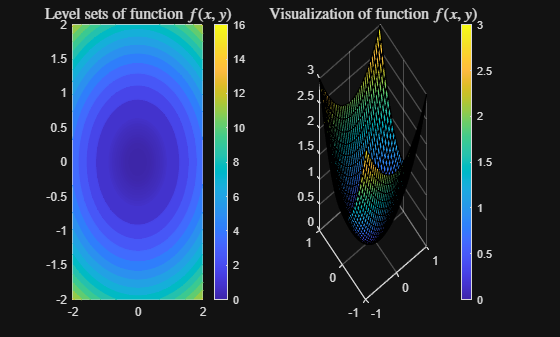


levels = linspace(0, 16, 20); 

figure;
subplot(1,2,1)
fcontour(f(x, y), [-2, 2, -2, 2], 'LevelList', levels, 'Fill', 'on')
colorbar
title('Level sets of function $f(x,y)$','Interpreter','latex','FontSize',12)
subplot(1,2,2)
fsurf(f(x,y), [-1, 1, -1, 1])
colorbar
title('Visualization of function $f(x,y)$','Interpreter','latex','FontSize',12)

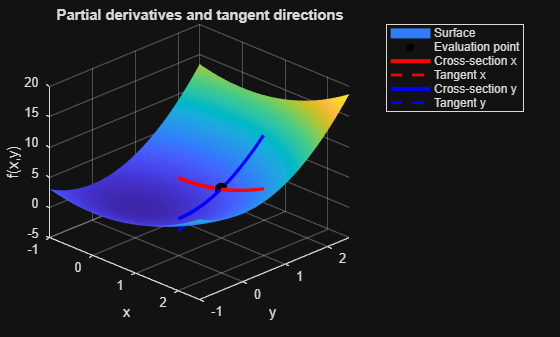

% Visualization of tangent lines, cross sections around (1,1) on the
% function f(x,y)

figure;

[X,Y] = meshgrid(-1:0.05:2.5, -1:0.05:2.5);
Z = X.^2 + 2*Y.^2;

surf(X,Y,Z,'EdgeColor','none');

hold on;

x0 = 1;
y0 = 1;
z0 = f(x0,y0);

scatter3(x0,y0,z0,100,'k','filled');

x = linspace(0,2,100);
y = ones(size(x));
z = f(x,y);

plot3(x,y,z,'r','LineWidth',3);

z_tan_x = z0 + 2*(x-x0);
plot3(x,y,z_tan_x,'r--','LineWidth',2);

y = linspace(0,2,100);
x = ones(size(y));
z = f(x,y);

plot3(x,y,z,'b','LineWidth',3);

z_tan_y = z0 + 4*(y-y0);
plot3(x,y,z_tan_y,'b--','LineWidth',2);

xlabel('x');
ylabel('y');
zlabel('f(x,y)');

title('Partial derivatives and tangent directions');

legend('Surface','Evaluation point', ...
    'Cross-section x','Tangent x', ...
    'Cross-section y','Tangent y');

view(45,30);
grid on;
hold off;

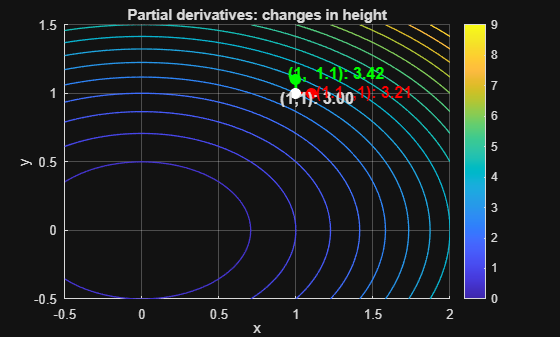

% Visualization of Partial Derivatives
clear 
f = @(x,y) x.^2 + 2*y.^2;

figure;
hold on;

fcontour(f,[-0.5 2 -0.5 2], ...
    'LevelList',0:0.5:9, ...
    'LineWidth',1);

x0 = 1;
y0 = 1;
h = 0.1;

Px = [x0+h,y0];
Py = [x0,y0+h];

z0 = f(x0,y0);
zx = f(Px(1),Px(2));
zy = f(Py(1),Py(2));

quiver(x0,y0,h,0,0,'r','LineWidth',2,'MaxHeadSize',2);
quiver(x0,y0,0,h,0,'g','LineWidth',2,'MaxHeadSize',2);

scatter(x0,y0,70,'w','filled');
scatter(Px(1),Px(2),70,'r','filled');
scatter(Py(1),Py(2),70,'g','filled');

text(x0-0.1,y0-0.04,sprintf('(1,1): %.2f',z0),'FontWeight','bold','FontSize',12);
text(Px(1)+0.03,Px(2),sprintf('(1.1  ,1): %.2f',zx),'Color','r','FontWeight','bold','FontSize',12);
text(Py(1)-0.05,Py(2)+0.04,sprintf('(1,  1.1): %.2f',zy),'Color','g','FontWeight','bold','FontSize',12);

xlim([-0.5 2])
ylim([-0.5 1.5])

xlabel('x');
ylabel('y');
title('Partial derivatives: changes in height');

grid on;
colorbar;
hold off;

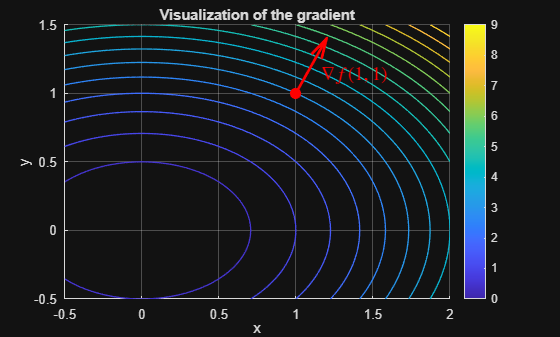

% Visualization of gradient 
clear 
f = @(x,y) x.^2 + 2*y.^2;

figure;
hold on;

fcontour(f,[-0.5 2 -0.5 2], ...
    'LevelList',0:0.5:9, ...
    'LineWidth',1);

x0 = 1;
y0 = 1;
h = 0.1;

quiver(x0,y0,2*h,4*h,0,'r','LineWidth',2,'MaxHeadSize',2);
scatter(x0,y0,70,'r','filled');

text(1.15,1.15,'$\nabla f(1,1)$', ...
    'Interpreter','latex', ...
    'FontSize',14, ...
    'FontWeight','bold','Color','r');

xlim([-0.5 2])
ylim([-0.5 1.5])

xlabel('x');
ylabel('y');
title('Visualization of the gradient');

grid on;
colorbar;
hold off;

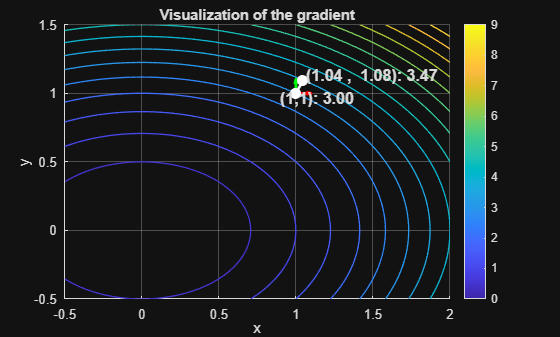

% comparing the gradient to moving in the x or y direction
clear
f = @(x,y) x.^2 + 2*y.^2;

figure;
hold on;

fcontour(f,[-0.5 2 -0.5 2], ...
    'LevelList',0:0.5:9, ...
    'LineWidth',1);

x0 = 1;
y0 = 1;
h = 0.1/sqrt(2^2 + 4^2);

P0 = [x0,y0];
P = [x0+2*h,y0+4*h];

z0 = f(x0,y0);
z = f(P(1),P(2));


quiver(x0,y0,2*h,4*h,0,'w','LineWidth',2,'MaxHeadSize',2);
quiver(x0,y0,h*sqrt(2^2 + 4^2),0,0,'r','LineWidth',2,'MaxHeadSize',2);
quiver(x0,y0,0,h*sqrt(2^2 + 4^2),0,'g','LineWidth',2,'MaxHeadSize',2);

scatter(x0,y0,70,'w','filled');

scatter(P(1),P(2),70,'w','filled');

text(x0-0.1,y0-0.04,sprintf('(1,1): %.2f',z0),'FontWeight','bold','FontSize',12);
text(P(1)+0.02,P(2)+0.04,sprintf('(1.04 ,  1.08): %.2f',z),'FontWeight','bold','FontSize',12);

xlim([-0.5 2])
ylim([-0.5 1.5])

xlabel('x');
ylabel('y');
title('Visualization of the gradient');

grid on;
colorbar;
hold off;

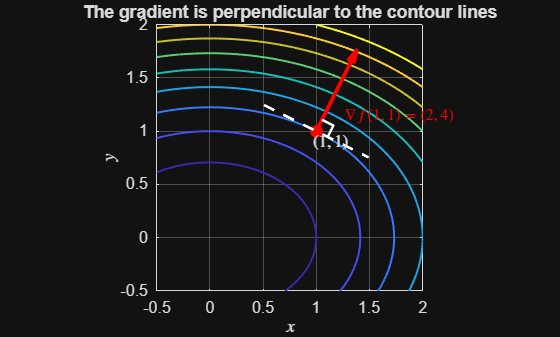

% the gradient is perpendicular to the level set
clear; 

f = @(x,y) x.^2 + 2*y.^2;
grad_f = @(x,y) [2*x; 4*y];

x0 = 1;
y0 = 1;

g = grad_f(x0,y0);

n = g/norm(g);
t = [n(2); -n(1)];

figure;
hold on;

levels = 1:1:9;

fcontour(f,[-2 2 -2 2], ...
    'LevelList',levels, ...
    'LineWidth',1.5);

scatter(x0,y0,90,'r','filled');

gradient_length = 0.85;

quiver(x0,y0, ...
    gradient_length*n(1), ...
    gradient_length*n(2), ...
    0,'r','LineWidth',2.8,'MaxHeadSize',0.5);

text(x0+0.25,y0+0.15, ...
    '$\nabla f(1,1)=(2,4)$', ...
    'Interpreter','latex', ...
    'FontSize',12,'Color','r', ...
    'FontWeight','bold');

tangent_length = 0.55;

plot([x0-tangent_length*t(1), ...
      x0+tangent_length*t(1)], ...
     [y0-tangent_length*t(2), ...
      y0+tangent_length*t(2)], ...
     'w--','LineWidth',2);

a = 0.12;

P1 = [x0;y0] + a*t;
P2 = P1 + a*n;
P3 = [x0;y0] + a*n;

plot([P1(1),P2(1),P3(1)], ...
     [P1(2),P2(2),P3(2)], ...
     'w','LineWidth',1.8);

text(x0-0.05,y0-0.1,'$(1,1)$', ...
    'Interpreter','latex','FontSize',13);

xlabel('$x$','Interpreter','latex','FontSize',15);
ylabel('$y$','Interpreter','latex','FontSize',15);

title('The gradient is perpendicular to the contour lines', ...
    'FontSize',12);

axis equal;
xlim([-0.5 2]);
ylim([-0.5 2]);

grid on;
box on;
set(gca,'FontSize',12);

hold off;

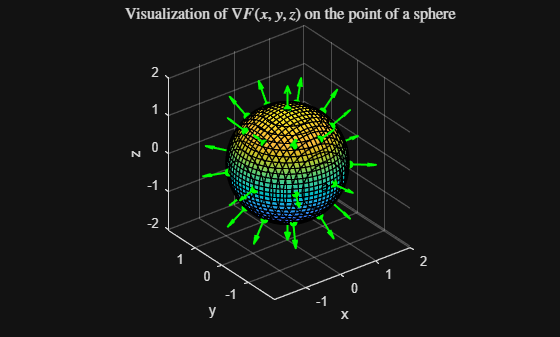

% illustrating that the gradient is the normal vector on a surface F(x,y,z)=c
clear
syms x y z
theta = linspace(0,2*pi,10);
phi = linspace(0,pi,5); 
r = sqrt(2);

[Theta,Phi] = meshgrid(theta,phi);
X = r*sin(Phi).*cos(Theta);
Y = r*sin(Phi).*sin(Theta);
Z = r*cos(Phi);


P = @(x,y,z) 2*x;
Q = @(x,y,z) 2*y;
R = @(x,y,z) 2*z;


figure; 
fimplicit3(x^2 + y^2 + z^2 - 2, [-2, 2, -2, 2, -2, 2])
hold on
scatter3(X,Y,Z,'filled','g')
axis equal;
quiver3(X, Y, Z, P(X,Y,Z), Q(X,Y,Z), R(X,Y,Z), 'g', 'LineWidth', 1.5)
xlabel('x');
ylabel('y');
zlabel('z');
title('Visualization of $\nabla F (x,y,z)$ on the point of a sphere','Interpreter','latex','FontSize',12)

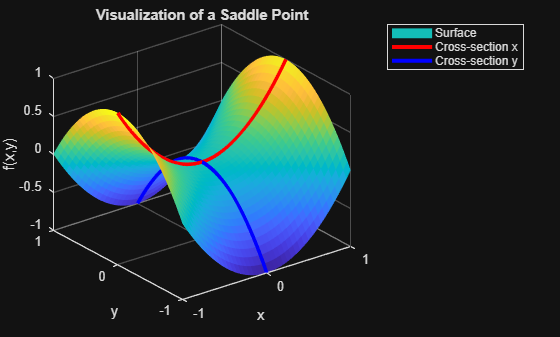

% illustration of a saddle point
clear
f = @(x,y) x.^2 - y.^2;

figure;
[X,Y] = meshgrid(-1:0.05:1, -1:0.05:1);
Z = X.^2 - Y.^2;

surf(X,Y,Z,'EdgeColor','none');
hold on;

x = linspace(-1,1,100);
y = zeros(size(x));
z = f(x,y);
plot3(x,y,z,'r','LineWidth',3);

y = linspace(-1,1,100);
x = zeros(size(y));
z = f(x,y);

plot3(x,y,z,'b','LineWidth',3);

xlabel('x');
ylabel('y');
zlabel('f(x,y)');

title('Visualization of a Saddle Point');

legend('Surface','Cross-section x','Cross-section y');

grid on;
hold off;